# Transport lattice

Transport lattice beam parameters

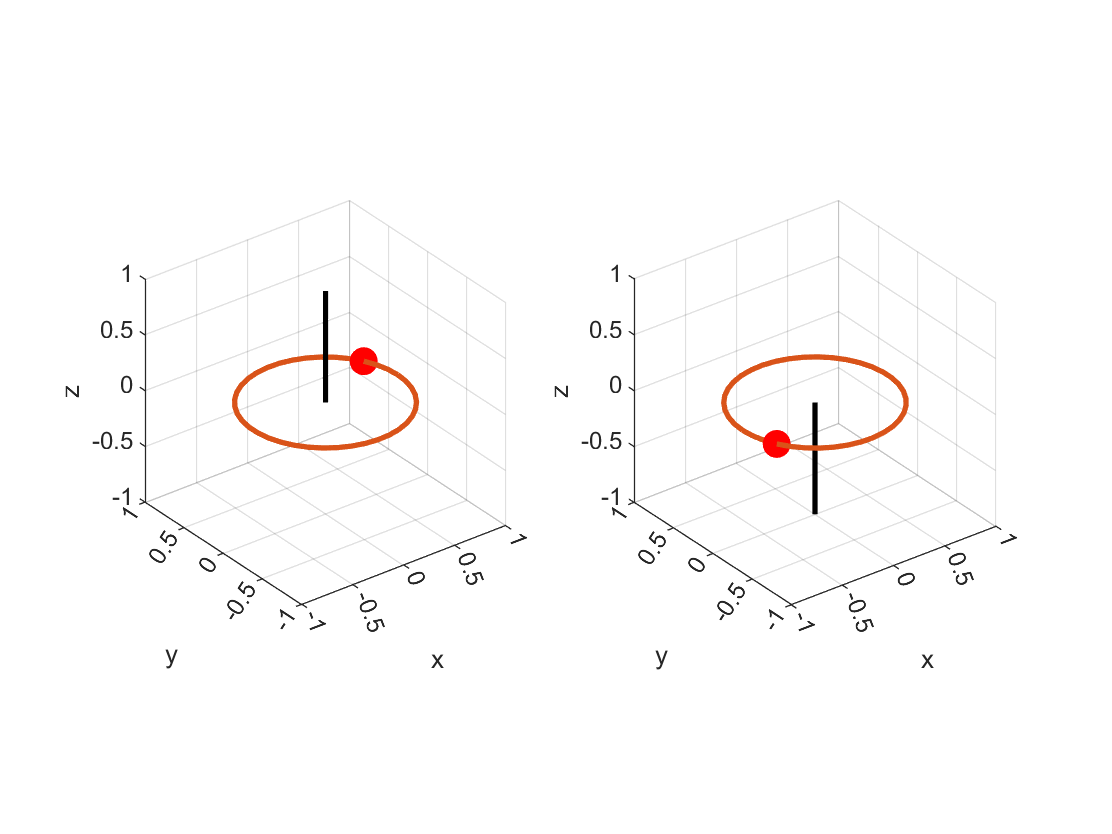

clear
clc

TransBeam.Power = [40000,32000];
TransBeam.Pol = [45,90;45,-90];
TransBeam.Wave = 1.064;
TransBeam.Ang = [0,0;0,180];
TransBeam.Waist = [300,300;300,300];

XRange = -70:70;
YRange = -100:100;
ZRange = -5:0.01:5;

XSize = length(XRange);
YSize = length(YRange);
ZSize = length(ZRange);

[Y,X,Z] = meshgrid(YRange,XRange,0.238);
[IXY,~,Pol,Dir] = gaussianFull(TransBeam,[X(:),Y(:),Z(:)]);

showPol(Pol,Dir)

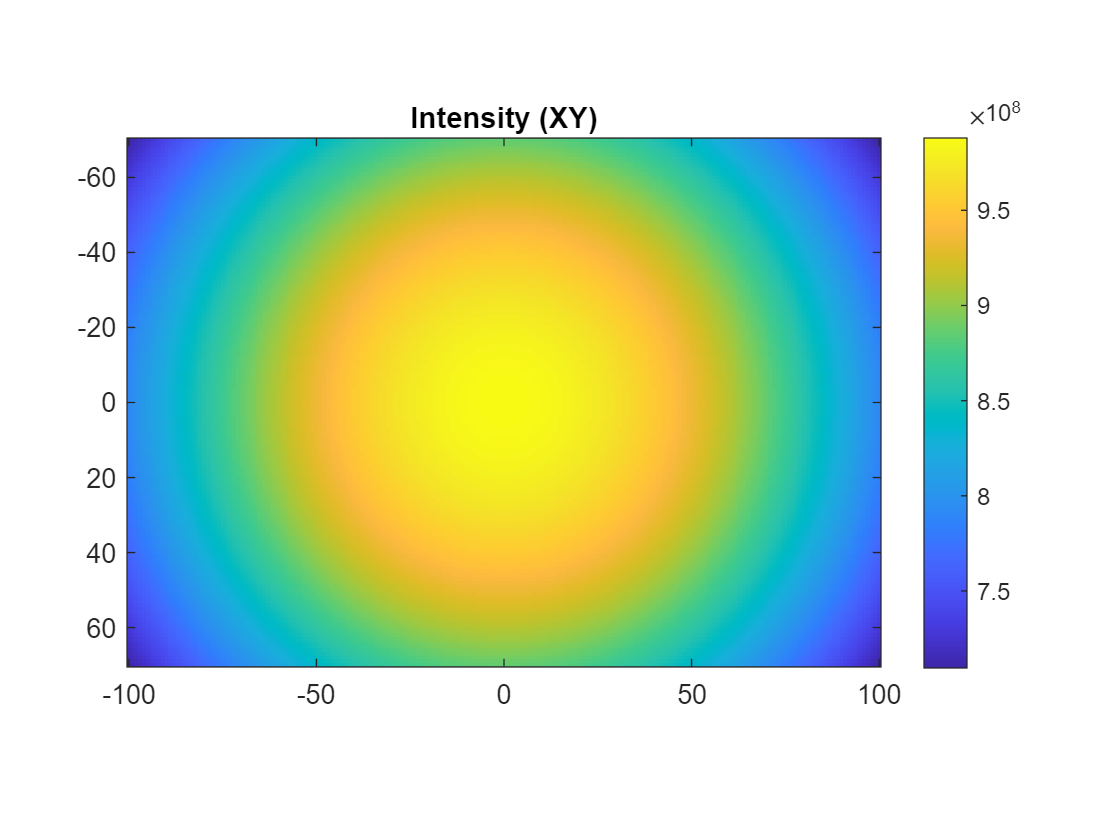

figure
imagesc(YRange,XRange,reshape(IXY,XSize,YSize))
colorbar
daspect([1 1 1])
title('Intensity (XY)')

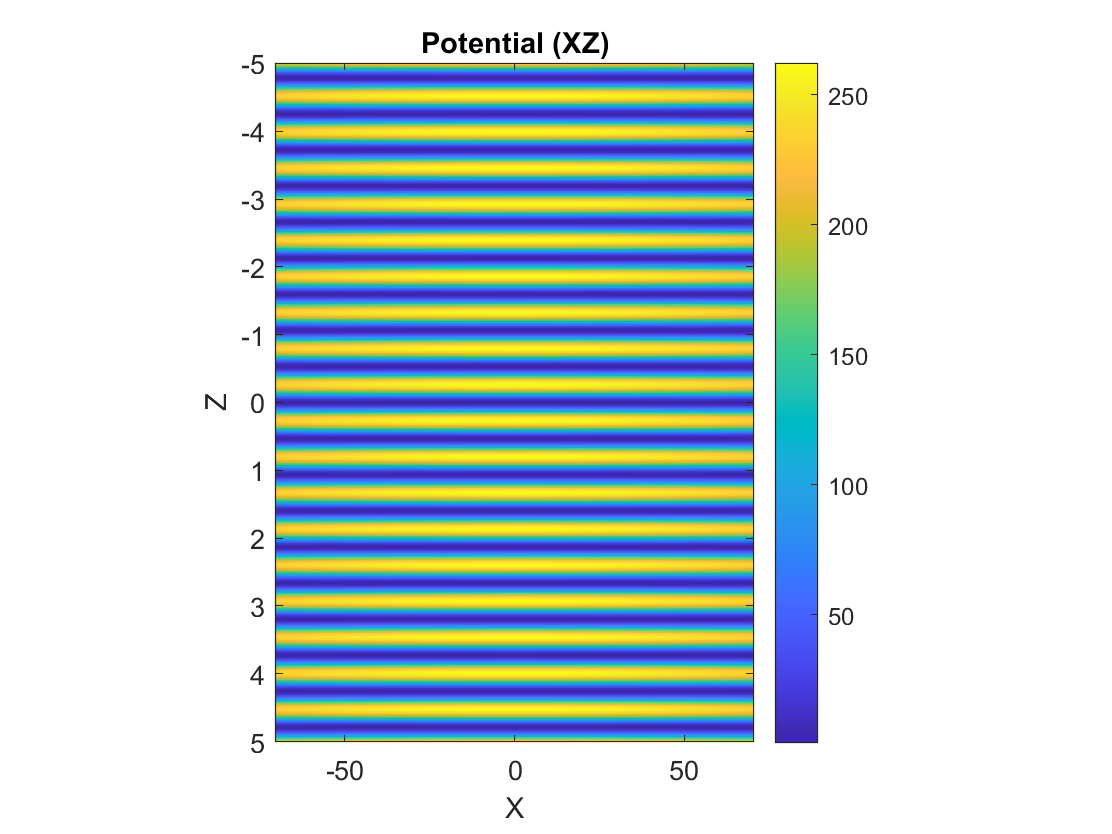

[Y,X,Z] = meshgrid(0,XRange,ZRange);
[IXZ,TotPol] = gaussianFull(TransBeam,[X(:),Y(:),Z(:)]);
PotenXZ = aNLJ('s',6,0,1/2,TransBeam.Wave,'ExpuK')*IXZ;
imagesc(XRange,ZRange,reshape(PotenXZ,XSize,ZSize)')
colorbar
daspect([20 1 1])
title('Potential (XZ)')
xlabel('X')
ylabel('Z')

[Freq,Vec] = fitTrapFreq([0 0 0], ...
    @(x) aNLJ('s',6,0,1/2,TransBeam.Wave,'Exp')*gaussianFull(TransBeam,x))

Freq = 1.0e+05 *

    0.0013
    0.0013
    1.6751


Vec =    -1.0000    0.0003    0.0000
   -0.0003   -1.0000   -0.0000
    0.0000   -0.0000    1.0000


#### Effective magnetic field

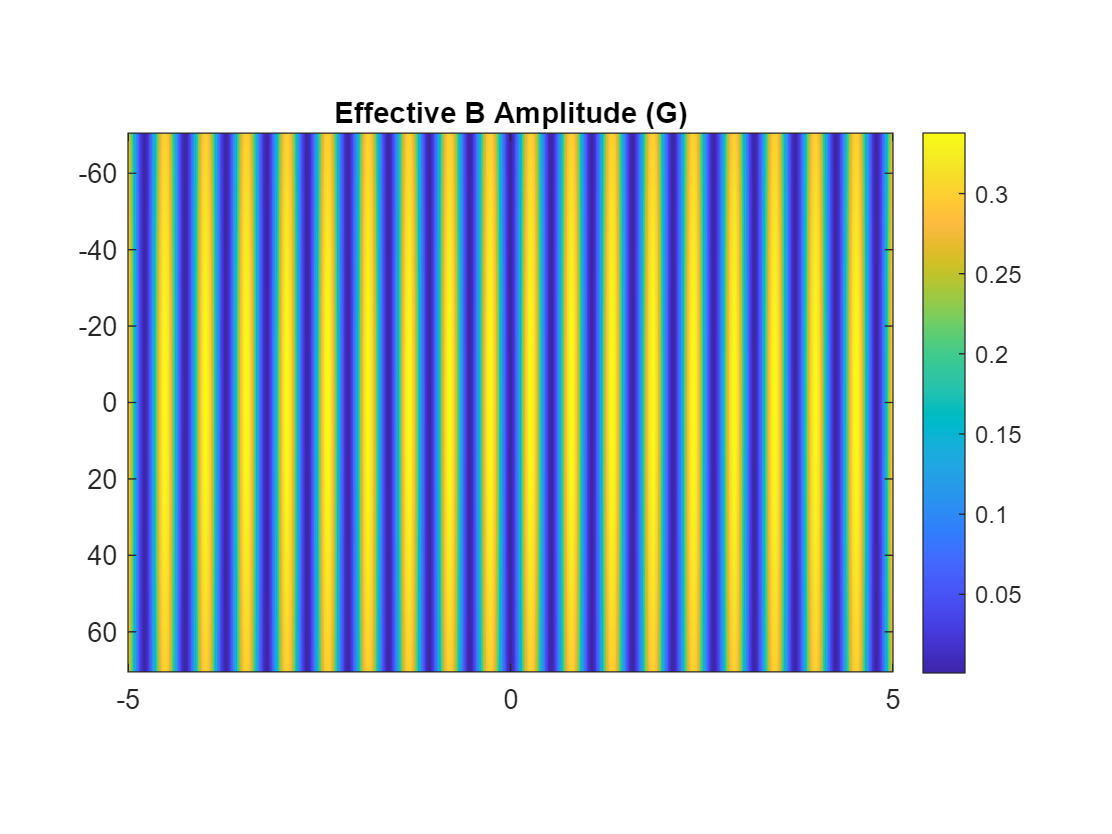

EffB = aNLJ('v',6,0,1/2,TransBeam.Wave,'ExpBFict')*1i*IXZ.*cross(conj(TotPol),TotPol,2);
EffBAmp = reshape(vecnorm(EffB,2,2),XSize,ZSize);
EffBDir = reshape(1i*cross(conj(TotPol),TotPol,2),XSize,ZSize,3);
EffBAng = zeros(XSize*ZSize,2);
[EffBAng(:,1),EffBAng(:,2)] = convertAxis2Ang(1i*cross(conj(TotPol),TotPol,2));
EffBAng = reshape(EffBAng,XSize,ZSize,2);

imagesc(ZRange,XRange,EffBAmp)
colorbar
daspect([1 20 1])
title('Effective B Amplitude (G)')

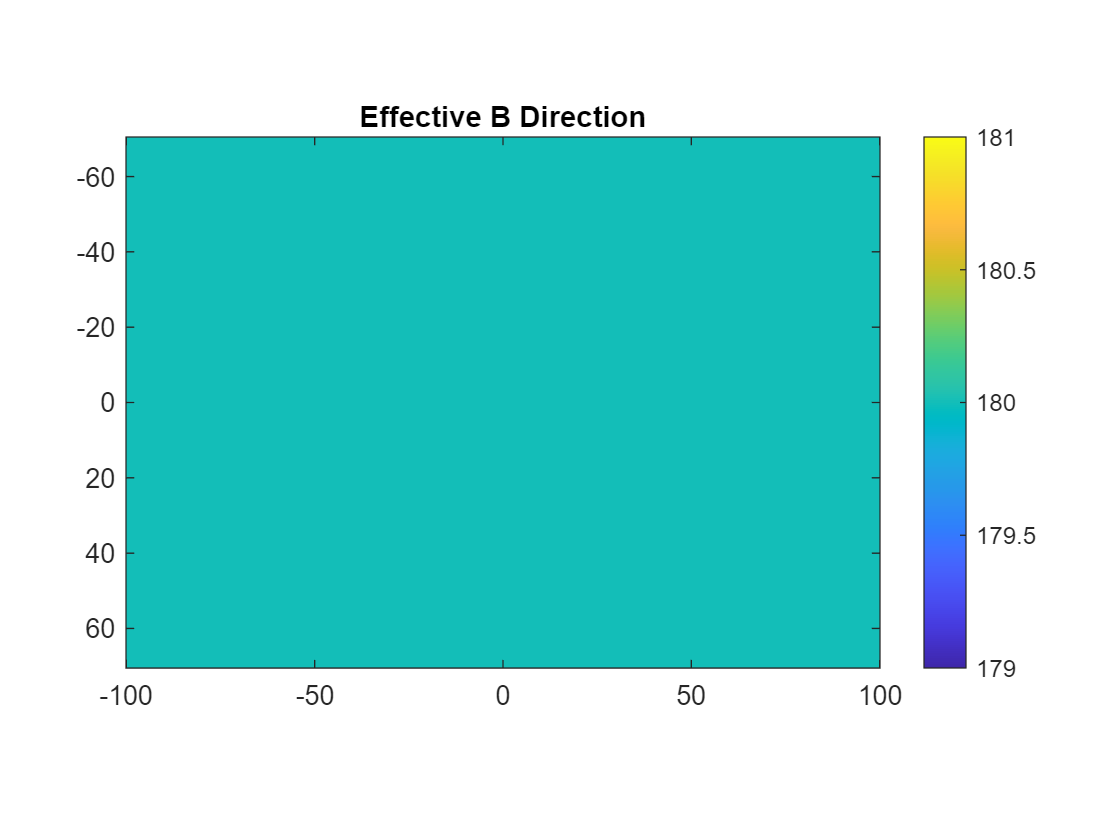

imagesc(YRange,XRange,EffBAng(:,:,2)*180/pi)
colorbar
daspect([1 1 1])
title('Effective B Direction')